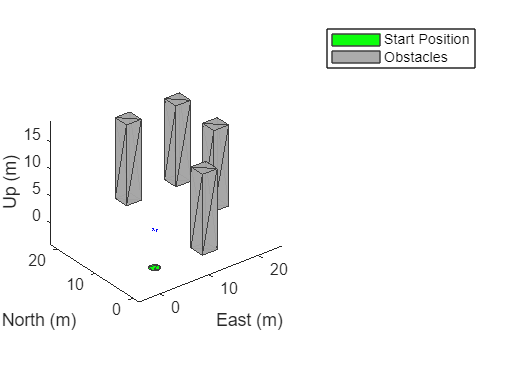

% Create a UAV scenario
Scenario = uavScenario("UpdateRate",100,"ReferenceLocation",[0 0 0]);

% Add a visual reference to the scenario
addMesh(Scenario,"cylinder",{[0 0 1] [0 .01]},[0 1 0]);

% Define initial position and orientation
InitialPosition = [0 0 -7];
InitialOrientation = [0 0 0];

% Create the UAV platform
platUAV = uavPlatform("UAV",Scenario, ...
                      "ReferenceFrame","NED", ...
                      "InitialPosition",InitialPosition, ...
                      "InitialOrientation",eul2quat(InitialOrientation));

% Update the UAV mesh
updateMesh(platUAV,"quadrotor",{1.2},[0 0 1],eul2tform([0 0 pi]));

% Define LiDAR parameters
AzimuthResolution = 0.5;      
ElevationResolution = 2;
MaxRange = 7;
AzimuthLimits = [-179 179];
ElevationLimits = [-15 15];
LidarModel = uavLidarPointCloudGenerator("UpdateRate",10, ...
                                         "MaxRange",MaxRange, ...
                                         "RangeAccuracy",3, ...
                                         "AzimuthResolution",AzimuthResolution, ...
                                         "ElevationResolution",ElevationResolution, ...
                                         "AzimuthLimits",AzimuthLimits, ...
                                         "ElevationLimits",ElevationLimits, ...                                       
                                         "HasOrganizedOutput",true);

% Attach LiDAR sensor to UAV
uavSensor("Lidar",platUAV,LidarModel, ...
          "MountingLocation",[0 0 -0.4], ...
          "MountingAngles",[0 0 180]);

% Define obstacle properties
ObstaclePositions = [20 20; 10 0; 20 10; 10 20]; % Locations of the obstacles
ObstacleHeight = 15;                      % Height of the obstacles
ObstaclesWidth = 3;                       % Width of the obstacles

% Add obstacles to the scenario
for i = 1:size(ObstaclePositions,1)
    addMesh(Scenario,"polygon", ...
        {[ObstaclePositions(i,1)-ObstaclesWidth/2 ObstaclePositions(i,2)-ObstaclesWidth/2; ...
        ObstaclePositions(i,1)+ObstaclesWidth/2 ObstaclePositions(i,2)-ObstaclesWidth/2; ...
        ObstaclePositions(i,1)+ObstaclesWidth/2 ObstaclePositions(i,2)+ObstaclesWidth/2; ...
        ObstaclePositions(i,1)-ObstaclesWidth/2 ObstaclePositions(i,2)+ObstaclesWidth/2], ...
        [0 ObstacleHeight]},0.651*ones(1,3));
end

% Display the scenario
show3D(Scenario);
legend("Start Position","Obstacles");

xlim([-4.3 24.8])
ylim([-1.5 21.5])
zlim([-4.0 19.0])


% Open and configure the Simulink model
open_system("ObstacleAvoidanceDemo.slx");

Unable to find system or file 'ObstacleAvoidanceDemo.slx'. 'ObstacleAvoidanceDemo' is used in 
  UAV Obstacle Avoidance in Simulink.

Waypoints = [InitialPosition; 0 20 -7; 15 13 -7; 20 0 -7];
for i = 2:size(Waypoints,1)
    addMesh(Scenario,"cylinder",{[Waypoints(i,2) Waypoints(i,1) 1] [0 0.1]},[1 0 0]);
end

% Display waypoints and direct path
show3D(Scenario);
hold on
plot3([InitialPosition(1,2); Waypoints(:,2)],[InitialPosition(1,2); Waypoints(:,1)],[-InitialPosition(1,3); -Waypoints(:,3)],"-g")
legend(["Start Position","Obstacles","","","Waypoints","","","Direct Path"]);

% Define PID controller parameters
Px = 6;
Py = 6;
Pz = 6.5;
Dx = 1.5;
Dy = 1.5;
Dz = 2.5;
Ix = 0;
Iy = 0;
Iz = 0;
Nx = 10;
Ny = 10;
Nz = 14.4947065605712;

% Additional UAV parameters
UAVSampleTime = 0.001;
Gravity = 9.81;
DroneMass = 0.1;

% Run the simulation
out = sim("ObstacleAvoidanceDemo.slx");

% Plot UAV trajectory
hold on
points = squeeze(out.trajectoryPoints(1,:,:))';
plot3(points(:,2),points(:,1),-points(:,3),"-r");
legend(["Start Position","Obstacles","","","Waypoints","","","Direct Path","UAV Trajectory"]);
